%First we must define the symbolic variables we will being using
clc, clear all;
syms a b t r

assume(t,'real') % parameter u should be real

Define the parametric curve

ri = 0.3960*cos(2.65*(0.2*t+1.4)); % i vector
rj = -0.99*sin(0.2*t+1.4); % j vector
rk = 0*t; % k vector
r=[ri,rj,rk]; % combined parametric curve

Compute linear speed and angular velocity

drdt = diff(r, t);
linear_velocity = drdt;
speed = norm(drdt);
tangent_vector = linear_velocity ./ speed;
tangent_vector = (tangent_vector);
dTdt = diff(tangent_vector,t);

normal_vector = dTdt./norm(dTdt);
angular_velocity = (cross(tangent_vector,dTdt));


Plot the parametric path and tangent & normal vectors

figure()
fplot(ri, rj, [0 16])
ylabel("r(t) (j component)")
xlabel("r(t) (i component)")
title("Parametric Curve of Bridge of Doom"+ newline + "Unit Tangent and Unit Normal vectors at time = 3, 11, 16 seconds")

hold on;

times = [3,11,16];
for time = times %plot T and N at specific times

    %Calculate starting point for tangent and unit vector
    i0 = double(subs(ri,{t},{time}));
    j0 = double(subs(rj,{t},{time}));
    plot(i0,j0,'.',MarkerSize=20,Color='black') %plot it as a point

    %Calculate end point for tangent vector
    Ti = tangent_vector(1); %isolate i component
    Tj = tangent_vector(2); %isolate j component
    Ti_cords = double(subs(Ti,{t},{time})); %calculate i component
    Tj_cords = double(subs(Tj,{t},{time})); %calculate j component

    %Calculate end point for normal vector
    Ni = normal_vector(1); %isolate i component
    Nj = normal_vector(2); %isolate j component
    Ni_cords = double(subs(Ni,{t},{time})); %calculate i component
    Nj_cords = double(subs(Nj,{t},{time})); %calculate j component
    
    quiver(i0,j0,Ti_cords,Tj_cords,Color='blue') %plot tangent vector
    quiver(i0,j0,Ni_cords,Nj_cords,Color='red') %plot normal vector
    legend('Bridge Path','Robot position','Unit Tangent Vector', 'Unit Normal Vector',Location='northwest')
end

%set axis size
domain = 1.5

domain = 1.5000

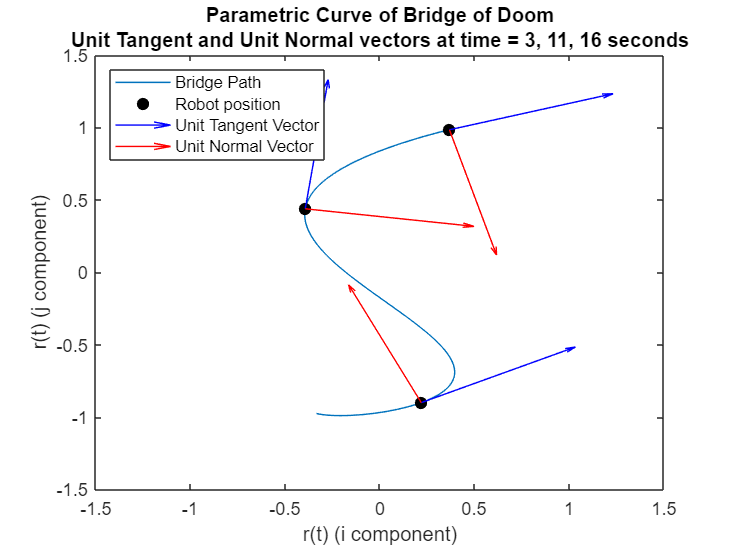

axis([-domain domain -domain domain])

hold off;

Encoder Stuff

Plot linear speed and angular velocity

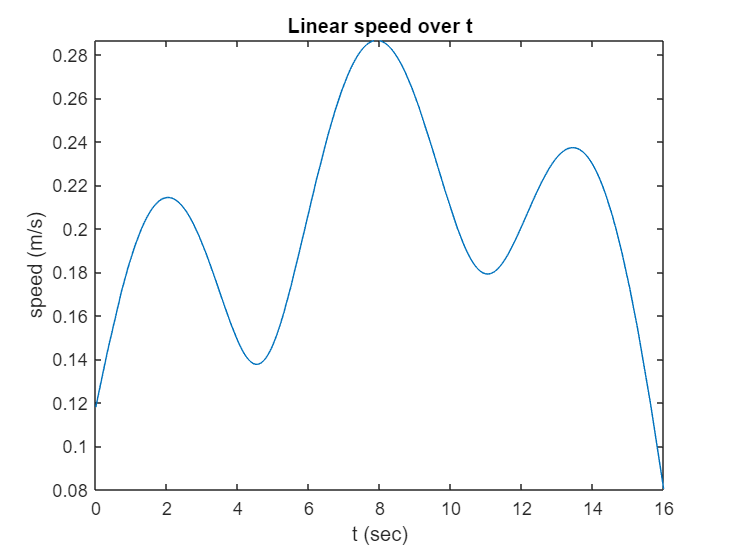

figure()
fplot(speed, [0 16])
ylabel("speed (m/s)")
xlabel("t (sec)")
title("Linear speed over t")

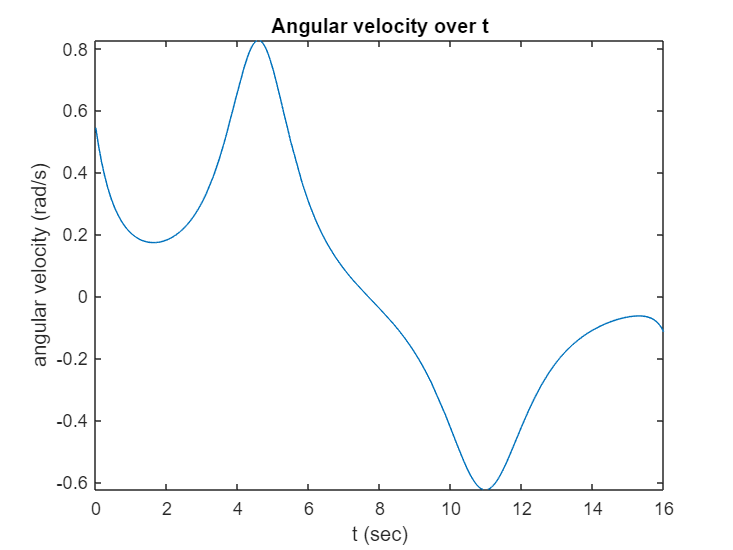


fplot(angular_velocity(3), [0 16])
ylabel("angular velocity (rad/s)")
xlabel("t (sec)")
title("Angular velocity over t")

Compute Left and Right wheel velocity

wheel_distance = 0.245;
velocity_left = speed - (angular_velocity) * (wheel_distance / 2);
velocity_right = speed + (angular_velocity) * (wheel_distance / 2);

Plot Left and Right wheel velocity

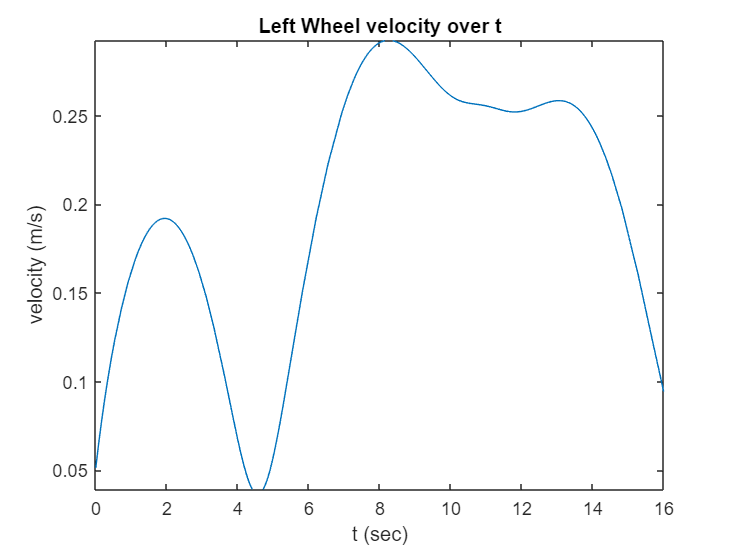

fplot(velocity_left(3), [0 16])
ylabel("velocity (m/s)")
xlabel("t (sec)")
title("Left Wheel velocity over t")

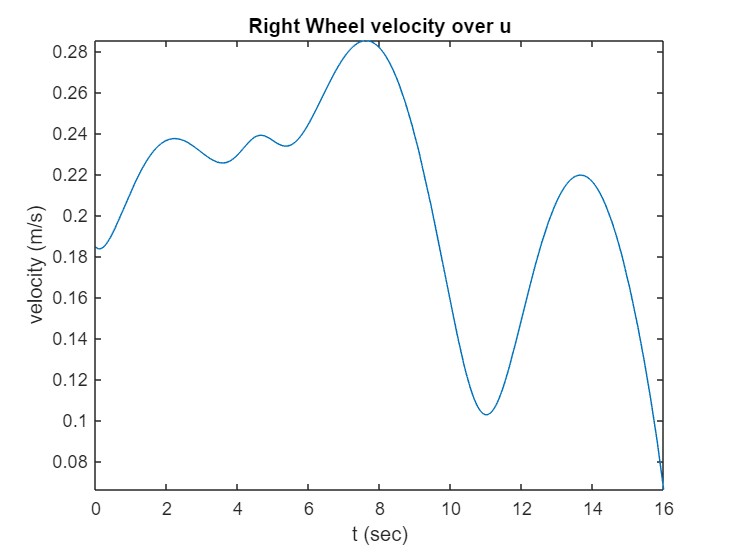

fplot(velocity_right(3), [0 16])
ylabel("velocity (m/s)")
xlabel("t (sec)")
title("Right Wheel velocity over u")